data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;
eye(2);
G1 = FWT(1:2,1:2);
s = tf('s');
G = G1.C*inv((s*eye(5)-G1.A))*G1.B;
omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
    end
RGA = frd(RGAw,omega)



G=tf(FWT(1:2,1:2))

wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/1000; % desired disturbance attenuation inside bandwidth
M=3 ; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A])
Wp=[Wp11 0; 0 wB2] %
%Sensitivity weight
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight

P11=[Wp;eye(2)];
P12=[Wp*G;Wu];
P21=eye(2);
P22=G;

%P=[P11 P12; P21 P22]
P = augw(minreal(G),Wp,Wu,Wt)
P1=minreal(P)


[K2,CL,GAM2,INFO2] = hinfsyn(P1,2,2) % Hinf design

K2 =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1      4.8   -4.439    34.78     1.33   -5.336    75.31     50.8   -134.7
   x2   0.7043  -0.7629   -5.443   0.1789    1.531   -13.42   -7.608    18.71
   x3    1.563   -1.198    11.48    0.734   -1.845    24.79     16.8   -44.45
   x4   -2.738    2.931   -20.86   -1.852  -0.3259   -45.96   -31.23    82.03
   x5   -34.36    32.77   -240.1   -15.61    39.96   -515.7   -350.7    933.6
   x6   -10.26     9.52   -73.36   -4.921    12.52   -158.2   -107.1    284.4
   x7    -18.9    20.57   -102.5   -9.372    12.44   -212.5   -151.6    409.9
   x8   -8.627    9.077   -50.25   -4.209    6.842   -105.4      -74    199.1
 
  B = 
               u1          u2
   x1    -0.05657  -2.387e-16
   x2    -0.01828   2.505e-16
   x3      0.1752   6.181e-16
   x4   -0.005088  -2.359e-17
   x5    -0.03053  -4.781e-17
   x6      0.2792  -7.315e-17
   x7      0.3099   5.919e-17
   x8     -0.8893   3.518e-16
 
  C

GAM2 = 0.6107

INFO2 =   hinfINFO with properties:

    gamma: 0.6107
        X: [8×8 double]
        Y: [8×8 double]
       Ku: [2×8 double]
       Kw: [2×8 double]
       Lx: [8×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]


L=G*K2+eye(2)

L =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11
   x1   -0.5979   -2.744   -1.177   -0.271  -0.3654        0        0        0        0        0   -37.13
   x2         4        0        0        0        0        0        0        0        0        0        0
   x3         0        1        0        0        0        0        0        0        0        0        0
   x4         0        0      0.5        0        0        0        0        0        0        0        0
   x5         0        0        0     0.25        0        0        0        0        0        0        0
   x6         0        0        0        0        0  -0.5979   -2.744   -1.177   -0.271  -0.3654   -8.133
   x7         0        0        0        0        0        4        0        0        0        0        0
   x8         0        0        0        0        0        0        1        0        0        0        0
   x9         0        0        0

PolesL=pole(minreal(L))

10 states removed.


PolesL =  -56.9265 + 0.0000i
   0.0220 + 3.5414i
   0.0220 - 3.5414i
  -0.0598 + 0.2136i
  -0.0598 - 0.2136i
  -0.0557 + 0.0630i
  -0.0557 - 0.0630i
  -0.0019 + 0.0000i


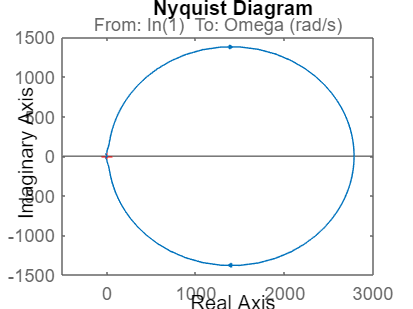

detL=L;
nyqDet=detL(1,1)*detL(2,2)-detL(1,2)*detL(2,1);
nyquist(nyqDet)

% Plot the Sensitivity
S = (1/Wp) *CL(1:2,1:2);

Error using indexing
Subscript no. 2 is out of range.

T = eye(2) - S;

figure()
step(S(1:2,1))
step(T(1:2,1))
stepinfo(T(1,1))
stepinfo(T(2,1))
